%assigning seed by using random number generator
clear all;
s=rng

s = struct with fields:
     Type: 'twister'
     Seed: 0
    State: [625×1 uint32]


%defining parameters M
%defining (n,k)autoencoder i.e..(n_channel,log2(M))=(2,2)autoencoder
M=4

M = 4

k=log2(M)

k = 2

n_channel=2

n_channel = 2

R=k/n_channel

R = 1

%generating data of size N
N=80 

N = 80

%calling the seed to get assign for the label
rng(s)
index =round((1 + (M-1)*rand(1,N)))

index =      3     3     3     2     3     2     3     2     3     2     2     3     3     1     4     3     2     2     2     2     3     3     3     3     3     2     3     3     2     4     4     3     3     3     2     2     2     2     4     2     2     2     2     2     2     4     2     2     4     4


%creating one hot encoded vectors
 j=1

j = 1

 while j<=N-1 %row
 for  i=index  %column
  temp=zeros(1,M);%zeros for matrix M
  i;
  temp(i)=1;%assigning one at that position
  index1=find(i);%finding index value i.e row
  data(j,:)=temp(:,:);%assiging temp value to data index value
  j=j+1;
  end
 end
  size(data)%checking data shape x train value

ans =     80     4


%checking generated data with its label
tempcheck=[17,23,51,66,5]

tempcheck =     17    23    51    66     5


for i=find(tempcheck)
index(i) 
data(i,:)
end

ans = 3

ans =      0     0     1     0


ans = 3

ans =      0     0     1     0


ans = 3

ans =      0     0     1     0


ans = 2

ans =      0     1     0     0


ans = 3

ans =      0     0     1     0


inputSize=4

inputSize = 4


for index = 1:(inputSize)
    mkdir(['./Data/' int2str(index)]); 
    matrixRep = reshape(oneHotFcn(index, inputSize), ...
        [sqrt(inputSize), sqrt(inputSize)]);
    imwrite(oneHotFcn(index, inputSize), ['./Data/' int2str(index) '/input.BMP']);

end

imds = imageDatastore('Data\', ...
    'IncludeSubfolders',true,'LabelSource','foldernames');
figure;

layer=[imageInputLayer([4 1 1])
        fullyConnectedLayer(4)
        ifftLayer
        fftLayer
        softmaxLayer
        classificationLayer]

layer =   6x1 Layer array with layers:

     1   ''   Image Input             4x1x1 images with 'zerocenter' normalization
     2   ''   Fully Connected         4 fully connected layer
     3   ''   ifftLayer               ifftLayer
     4   ''   fftLayer                fftLayer
     5   ''   Softmax                 softmax
     6   ''   Classification Output   crossentropyex

 options = trainingOptions('adam', ...
     'InitialLearnRate',0.01, ...
     'MaxEpochs',100, ...
     'VerboseFrequency',50,...
     'MiniBatchSize',128,...
     'Plots','training-progress',...
     'Shuffle','never')

options =   TrainingOptionsADAM with properties:

           GradientDecayFactor: 0.9000
    SquaredGradientDecayFactor: 0.9990
                       Epsilon: 1.0000e-08
              InitialLearnRate: 0.0100
     LearnRateScheduleSettings: [1×1 struct]
              L2Regularization: 1.0000e-04
       GradientThresholdMethod: 'l2norm'
             GradientThreshold: Inf
                     MaxEpochs: 100
                 MiniBatchSize: 128
                       Verbose: 1
              VerboseFrequency: 50
                ValidationData: []
           ValidationFrequency: 50
            ValidationPatience: Inf
                       Shuffle: 'never'
                CheckpointPath: ''
          ExecutionEnvironment: 'auto'
                    WorkerLoad: []
                     OutputFcn: []
                         Plots: 'training-progress'
                SequenceLength: 'longest'
          Seque

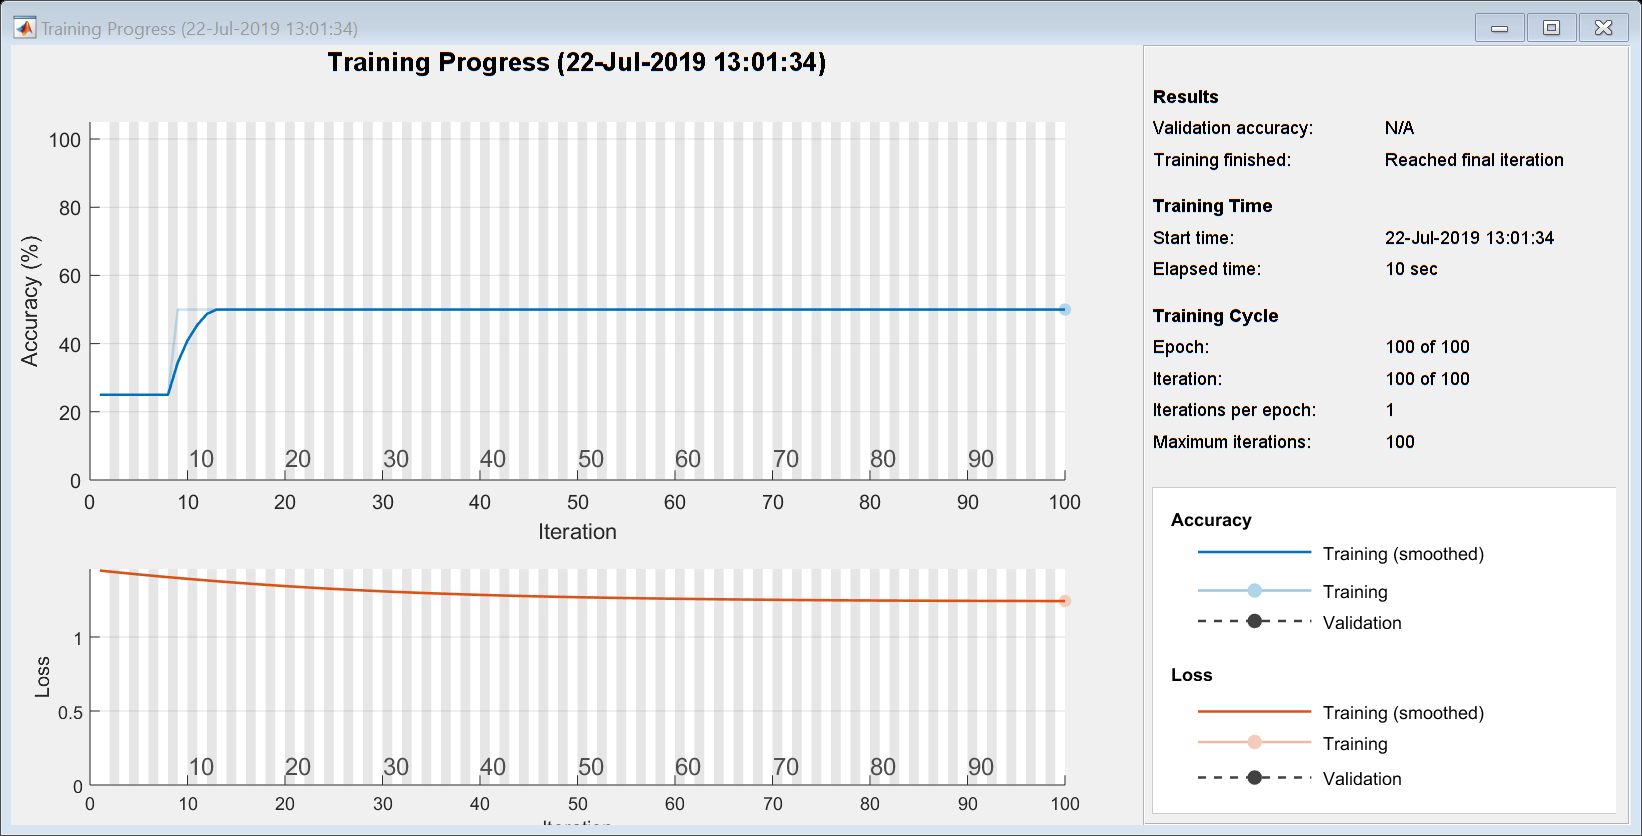

Training on single CPU.


Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:03 |       25.00% |       1.4490 |          0.0100 |
|      50 |          50 |       00:00:07 |       50.00% |       1.2688 |          0.0100 |
|     100 |         100 |       00:00:10 |       50.00% |       1.2428 |          0.0100 |
|========================================================================================|


net =   SeriesNetwork with properties:

    Layers: [6×1 nnet.cnn.layer.Layer]


 net = trainNetwork(imds,layer,options)

function vec = oneHotFcn(int, max) 
vec = bsxfun(@eq, 1:max, int+1);
vec = transpose(vec);
end